# Kometenbahn

## Aufgabe: Ensamble

## Gegebener Teil: Tabelle und Plot

close all
data = readtable("komet_karthesisch.csv");  % CSV-Daten einlesen -> Ergebniss: Tabelle

data=data(1:25,:) % Daten auf die ersten 25 Messpunkte beschränken

data = 25×4 table
       x_T            x             y         z
    __________    __________    __________    _

             0      7.48e+12             0    0
    3.9789e+07    7.4781e+12    3.9785e+09    0
    7.9577e+07    7.4725e+12     7.955e+09    0
    1.1937e+08     7.463e+12    1.1928e+10    0
    1.5915e+08    7.4498e+12    1.5894e+10    0
    1.9894e+08    7.4328e+12    1.9852e+10    0
    2.3873e+08    7.4119e+12      2.38e+10    0
    2.7852e+08    7.3873e+12    2.7736e+10    0
    3.1831e+08    7.3587e+12    3.1657e+10    0
     3.581e+08    7.3263e+12    3.5562e+10    0
    3.9789e+08    7.2899e+12    3.9447e+10    0
    4.3767e+08    7.2496e+12    4.3311e+10    0
    4.7746e+08    7.2052e+12    4.7151e+10    0
    5.1725e+08    7.1568e+12    5.0965e+10    0
    5.5704e+08    7.1043e+12    5.4749e+10    0
    5.9683e+08    7.0476e+12 

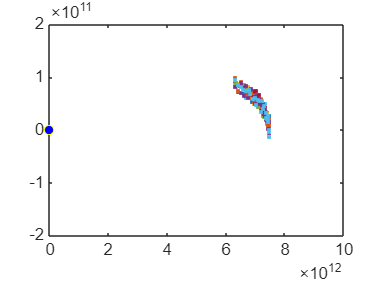

figure
% Originaldaten plotten
plot(data.x, data.y,'.')    
hold on

% Schleife mit 10 durchläufen um die 
% 10 leicht veränderten Datensätze zu erzeugen
for k=1:10
    
    % Erstellen von einem verrauschten Datensatz: soll Messunsicherheit
    % simulieren
    data_tmp=addNoise(data);
    plot(data_tmp.x, data_tmp.y,'.')    % Plot der verrauschten  Daten 
    hold on
    plot(0,0,'yo','MarkerFaceColor','b', 'MarkerSize',5)    % Zusatz: Erde
end
axis([0 1e13 -2e11 2e11])       % feste Achsengrenzen
hold off

## Funktion zur Erzeugung von Messrauschen

% funktion welche ein normalverteiltes Rauschen zum og. Datensatzhinzufügt
% Eingabe: saubere Daten
% Ausgabe: saubere Daten + Rauschen

function noisyData=addNoise(cleanData)
% skalieren des Rauschen. Messfehler nehmen mit der Entfernung zu. r ist
% der Abstand jedes Punktes zu Ursprung
r = hypot(cleanData.x, cleanData.y)*1e-3;

% Erzeugen von normalverteiltem Rauschen mittels randn
noise_x=randn(size(r)).*r;
noise_y=randn(size(r)).*r;

% Addieren des Rauschen zu den Messdaten
% Messabweichung Simulieren
noisyData = cleanData;
noisyData.x = cleanData.x + noise_x;
noisyData.y = cleanData.y + noise_y;
end

## Ensemble-Auswertung: minimaler Abstand

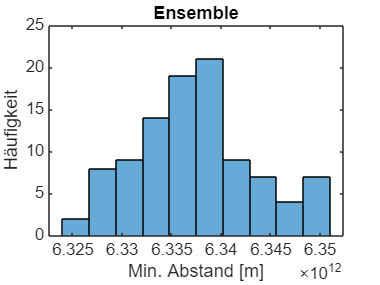

% das Ensemble aus statistischen Gründen auf Realisierungen = 100 erweitert

% Initialisieren von Vektor: Speicher für 100 minimale Abstände
minDist = zeros(100,1);   


% Schleife mit 100 Ensmble-Realisierungen
for k = 1:100

    % 1) neuen verrauschten Datensatz erzeugen
    data_tmp = addNoise(data);

    % 2) Abstand jedes Punkts zur Erde (0,0) berechnen
    %    Abstand = (x^2+y^2)^0,5    (Pythogoras)
    dist = hypot(data_tmp.x, data_tmp.y);

    % 3) kleinsten Abstand speichern
    minDist(k) = min(dist);
end

% Visualisierung: Histogramm der minimalen Abstände
figure
histogram(minDist, 10)  % Erstellt ein Histogramm der min. Abstände (10 Klassen)
xlabel('Min. Abstand [m]')
ylabel('Häufigkeit')
title('Ensemble')

## Erweiterung: Zufallseinfluss

% Ensemble für 10 Realisierungen
% weniger Realisierungen -> schlechtere Statistik
% Histogramme mit weniger Daten sind instabiler
% Bei nur 10 Realisierungen ist der Zufallseinfluss groß
% siehe vergleich V1 und V2

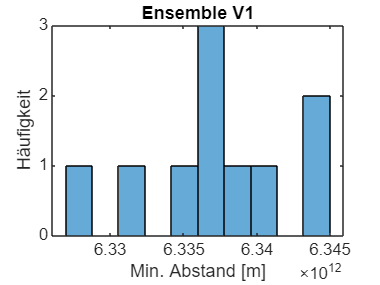

% Ensemble V1

minDist_1 = zeros(10,1);   
for k = 1:10
    data_tmp = addNoise(data);
    dist_1 = hypot(data_tmp.x, data_tmp.y);
    minDist_1(k) = min(dist_1);
end
figure
histogram(minDist_1, 10)  
xlabel('Min. Abstand [m]')
ylabel('Häufigkeit')
title('Ensemble V1')

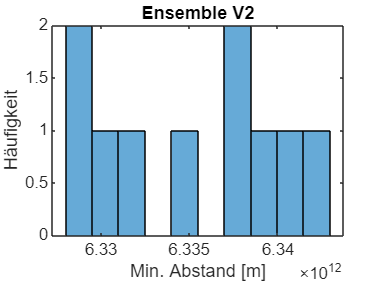

%Ensemble V2

minDist_2 = zeros(10,1);   
for k = 1:10
    data_tmp = addNoise(data);
    dist_2 = hypot(data_tmp.x, data_tmp.y);
    minDist_2(k) = min(dist_2);
end
figure
histogram(minDist_2, 10)  
xlabel('Min. Abstand [m]')
ylabel('Häufigkeit')
title('Ensemble V2')